This function has infinitely many continuous derivatives on the entire real line and looks very easy to approximate over $[-1,1]$. 

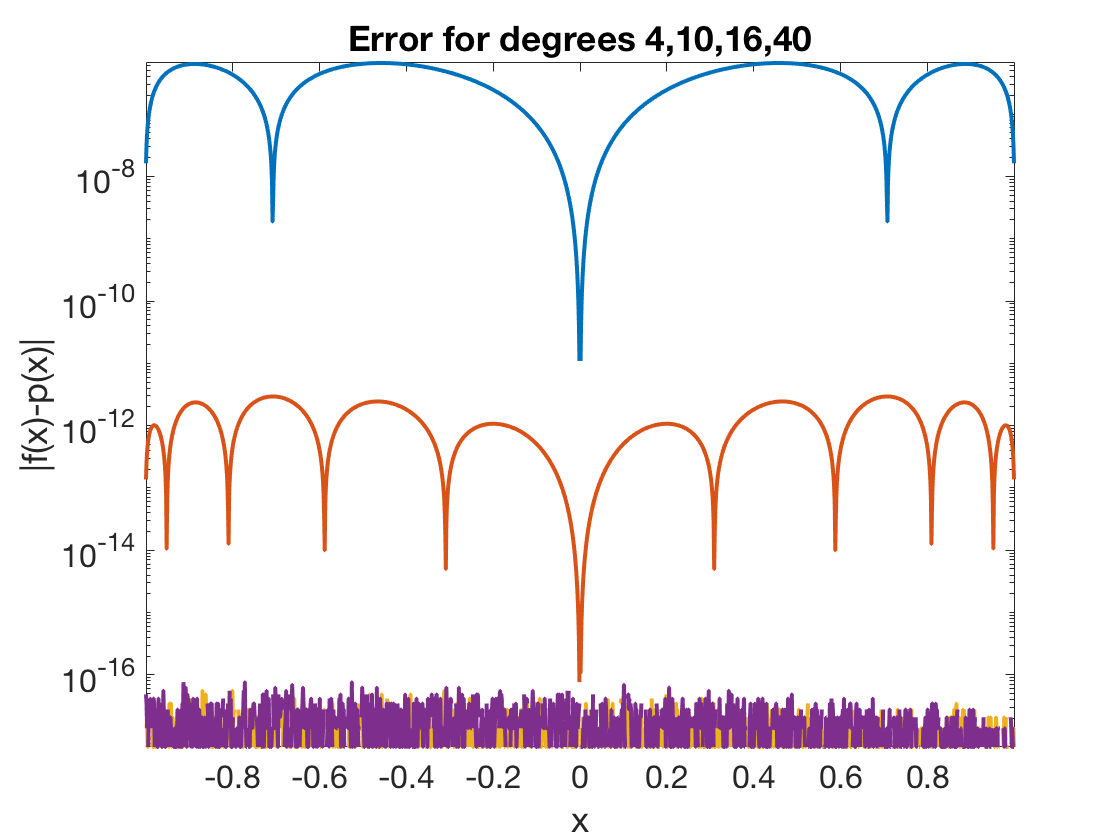

f = @(x) 1./(x.^2 + 16);
x = linspace(-1,1,1601)';
n = [4 10 16 40];
for k = 1:length(n) 
    theta = linspace(0,pi,n(k)+1)';
    t = -cos(theta);
    p = polyinterp(t,f(t));
    semilogy( x, abs(f(x)-p(x)) );
    hold on, axis tight    % ignore this line
end
axis tight, title('Error for degrees 4,10,16,40')   % ignore this line
xlabel('x'), ylabel('|f(x)-p(x)|')   % ignore this line

By degree 16 the error is uniformly within machine epsilon. Note that even as the degree continues to increase, the error near the ends does not grow as with the Runge phenomenon for equally spaced nodes.